clc
clear all
close all

**Read Prices**

load myPrice_dt.mat
load array_prices

**Selection of a subset of Dates**

start_dt = datetime('01/01/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt = datetime('01/01/2022', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'closed');
subsample = myPrice_dt(rng, :);
prices_val = subsample.Variables;
dates_ = subsample.Time;

**Compute Moments**

LogRet = tick2ret(prices_val, 'Method', 'continuous');
ExpRet = mean(LogRet);
CovMatrix = cov(LogRet);

**PCA**

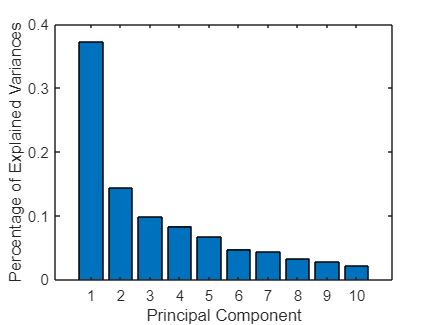

k = 10;
[factorLoading, factorRetn, latent] = pca(LogRet, 'NumComponents', k);

ToTVar = sum(latent);
ExplainedVar = latent(1:k)/ToTVar;

n_list = [1,2,3,4,5,6,7,8,9,10];
CumExplainedVar = zeros(1, size(n_list, 2));

for i = 1:size(n_list, 2)
    n = n_list(i);
    CumExplainedVar(1, i) = getCumulativeExplainedVar(latent, n);
end

figure;
title('Percenatge of Explained Variances for each principal component')
bar(n_list, ExplainedVar)
xlabel('Principal Component')
ylabel('Percentage of Explained Variances')

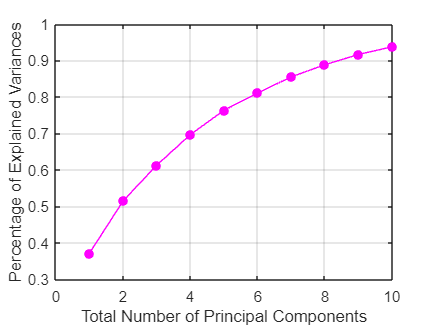


figure;
title('Total Percentage of Explained Variances for the first n-components')
plot(n_list, CumExplainedVar, 'm')
hold on
scatter(n_list, CumExplainedVar, 'm', 'filled')
grid on
xlabel('Total Number of Principal Components')
ylabel('Percentage of Explained Variances')


%reconstruct asset returns
covarFactor = cov(factorRetn);
reconReturn = factorRetn*factorLoading' + ExpRet;
unexplainedRetn = LogRet-reconReturn;

%There are unexplained asset returns beacuase the remaining (p-k) principal
%components ??
unexplainedCovar = diag(cov(unexplainedRetn));
D = diag(unexplainedCovar);

covarAsset = factorLoading*covarFactor*factorLoading'+D;

**Optimization max(ret-variance)**

func = @(x) -((ExpRet*x)-((factorLoading'*x)'*covarFactor*(factorLoading'*x)+x'*D*x));

x0 = rand(size(LogRet,2),1);
x0 = x0./sum(x0);
lb = zeros(1,size(LogRet,2));
ub = ones(1,size(LogRet,2));
Aeq = ones(1,size(LogRet,2));
beq = 1;

[w_opt, fval] = fmincon(func, x0, [], [], Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



%equity curve & performance
ret = prices_val(2:end, :)./prices_val(1:end-1,:);
equity_ = cumprod(ret*w_opt);
equity_ = 100.*equity_/equity_(1);
[annRet_, annVol_, Sharpe_, MaxDD_, Calmar_] = getPerformanceMetrics(equity_);

perfTable = table(annRet_, annVol_, Sharpe_, MaxDD_, Calmar_, 'VariableNames', ["AnnRet", "AnnVol", "Sharpe", "MaxDD", "Calmar"])

perfTable = 1×5 table
    AnnRet    AnnVol     Sharpe     MaxDD      Calmar
    ______    _______    ______    ________    ______

    1.4332    0.38255    3.7464    -0.21381    6.703 



%Plot Equity pca VS equity EW
wEW = 1/15 * ones(15,1);
equity_ew = cumprod(ret*wEW);
eqiuty_ew = 100.*equity_ew/equity_ew(1);
[annRet_ew, annVol_ew, Sharpe_ew, MaxDD_ew, Calmar_ew] = getPerformanceMetrics(equity_ew);
perfTable_ew = table(annRet_ew, annVol_ew, Sharpe_ew, MaxDD_ew, Calmar_ew, 'VariableNames', ["AnnRet", "AnnVol", "Sharpe", "MaxDD", "Calmar"])

perfTable_ew = 1×5 table
    AnnRet     AnnVol     Sharpe      MaxDD      Calmar
    _______    _______    ______    _________    ______

    0.37235    0.14278    2.6078    -0.052316    7.1172


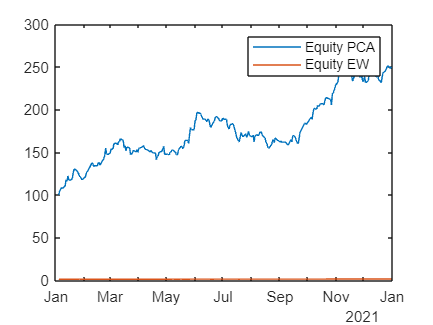

%Plot
figure;
plot(dates_(2:end,1),equity_)
hold on
plot(dates_(2:end,1), equity_ew)
legend('Equity PCA', 'Equity EW')

**Sensitivity Analysis + Optimization MaxSharpe**

k_list = [2, 5, 7, 10, 12];
x0 = rand(size(LogRet,2),1);
x0 = x0./sum(x0);
lb = zeros(1,size(LogRet,2));
ub = ones(1,size(LogRet,2));
Aeq = ones(1,size(LogRet,2));
beq = 1;

weights_pca = zeros(size(LogRet,2), size(k_list,2));
equity_matrix = zeros(size(equity_ew,1), size(k_list,2));
perf_table = table('Size', [5 5], 'VariableTypes', {'double', 'double', 'double','double','double'}, 'VariableNames', {'AnnRet', 'AnnVol', 'Sharpe', 'MaxDD', 'Calmar'}, 'RowNames', {'k=2', 'k=5', 'k=7', 'k=10', 'k=12'});

for i = 1:size(k_list,2)
    k = k_list(i);
    [factorLoading, factorRetn, latents] = pca(LogRet, 'NumComponents', k);
    covarFactor = cov(factorRetn);
    reconReturn = factorRetn * factorLoading' + ExpRet;
    unexplainedRetn = LogRet - reconReturn;
    unexplainedCovar = diag(cov(unexplainedRetn));
    D = diag(unexplainedCovar);
    covarAsset = factorLoading*covarFactor*factorLoading'*D;
    f_max_sharpe = @(x) -((ExpRet')/sqrt((factorLoading'*x)'*covarFactor*(factorLoading'*x))+x'*D*x);
    w_opt = fmincon(f_max_sharpe, x0, [], [], Aeq, beq, lb, ub);
    weights_pca(:,i) = w_opt;
    equity_temp = cumprod(ret*w_opt);
    equity_temp = 100.*equity_temp/equity_temp(1);
    equity_matrix(:,i) = equity_temp;
    [annRet_, annVol_, Sharpe_, MaxDD_, Calmar] = getPerformanceMetrics(equity_matrix);
    perf_table(i,:) = table(annRet_, annVol_, Sharpe_, MaxDD_, Calmar_, 'VariableNames', ["AnnRet", "AnnVol", "Sharpe", "MaxDD", "Calmar"]);
end

Error using fmincon
Supplied objective function must return a scalar value.

figure;
plot(dates(2:end, 1), equity_ew, 'k')
hold on
plot(dates_(2:end,1), equity_matrix)
legend('k=2', 'k=5', 'k=7', 'k=10', 'k=12', 'EW')
